# Power Spectral Density

## Power Spectral Density

### Definition

Power spectral density is used to characterise stationary random processes in the frequency domain. Power Spectral Density is defined as follows:

        
$$S_{\mathrm{xx}} \left(\omega \right)=R_{\mathrm{xx}} \left(e^{j\omega } \right)=\sum_{\ell =-\infty }^{\infty } r_{\mathrm{xx}} \left(\ell \right)e^{-\jmath \ell \omega }$$


Essentially, Power Spectral Density is the discrete-time Fourier Transform of the auto-correlation sequence $r_{\mathrm{xx}} \left(\ell \right)$.

**Notice that phases disappear when we compute the spectrum.**

`INSIGHT`*:* If we have a signal with some oscillation, the oscilation is observed in the autocorrelation. Taking the Fourier Transform of the same autocorrelation, we will observe that there is energy at that particular frequency.

We can go the opposite direction. Given the PSD, we can compute the auto-correlation sequence by the inverse Fourier Transform as follows:

        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{1}{2\pi }\int_{-\pi }^{\pi } S_{\textrm{xx}} \left(\omega \right)e^{\;j\omega \ell } \;\mathrm{d}\omega$$


### What is the average power of a stable LTI system?

Suppose we want to know the average output of the filter i.e., $E\left\lbrack y^2 \left(n\right)\right\rbrack$

The average output of a filter is actually just the value of the autocorrelation at lag 0. How? We can see this if look at the expression from a different perspective:

        
$$E\left\lbrack y^2 \left(n\right)\right\rbrack =E\left\lbrack y\left(n\right)y\left(n-0\right)\right\rbrack =r_y \left(0\right)$$


Using the inverse definition of the PSD, we can compute $r_y \left(0\right)$

        
$$r_y \left(0\right)=\frac{1}{2\pi }\int_{-\pi }^{\pi } S_{\textrm{xx}} \left(\omega \right)e^{\;j\omega \cdot 0} \;\mathrm{d}\omega$$


                 
$$=\frac{1}{2\pi }\int_{-\pi }^{\pi } S_{\textrm{xx}} \left(\omega \right)\;\mathrm{d}\omega$$


If we integrate the PSD from $-\pi$ to $\pi$, the resulting quantity is equal to the power in the time-domain. This means that **energy in the time-domain is equal to energy in the frequency domain**.

Another perspective:

Let $P_{\mathrm{ab}}$ be a normalised integration of the PSD from the interval $\omega_a$ to $\omega_b$. The quantity $P_{\mathrm{ab}}$ is the expected (or average) contribution to the total power (or variance) that is due to the components of the random process between $\omega_a$ and $\omega_b$. In other words, the area under the curve between  $\omega_a$ and $\omega_b$ is the power that that portion of the spectrum is expected to contribute to the random process. It tells us how power is distrubuted in a frequency spectrum.

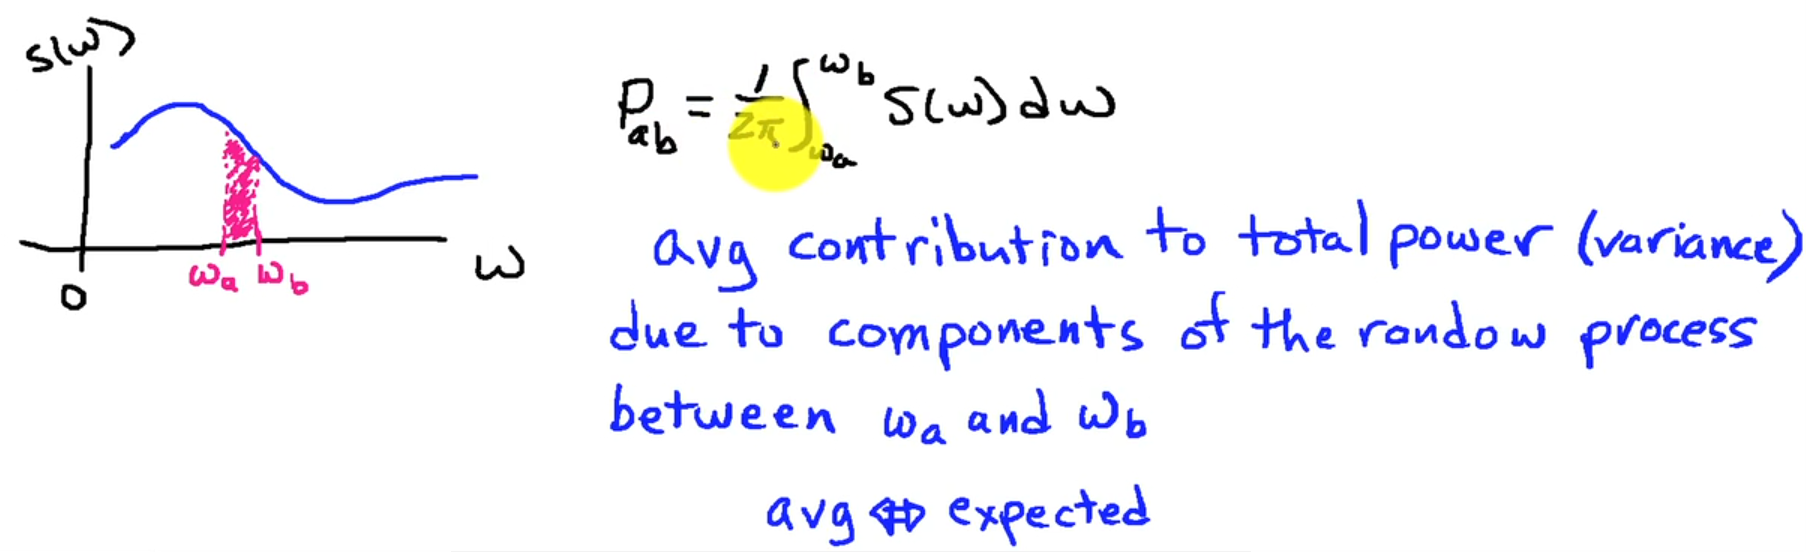

#### Example: Power Spectrum Analyser

Suppose we want to know the power spectrum of some input signal $x\left\lbrack n\right\rbrack$. We can pass that signal to an ideal bandpass filter with very narrow band and compute the power at the output. We define the bandpass filter to have the unit response in the vecinity of $\omega_c$ and the band $\Delta \omega$ is very small. Our bandpass filter rejects frequencies outside $\Delta \omega$ and pass any frequency inside this band.

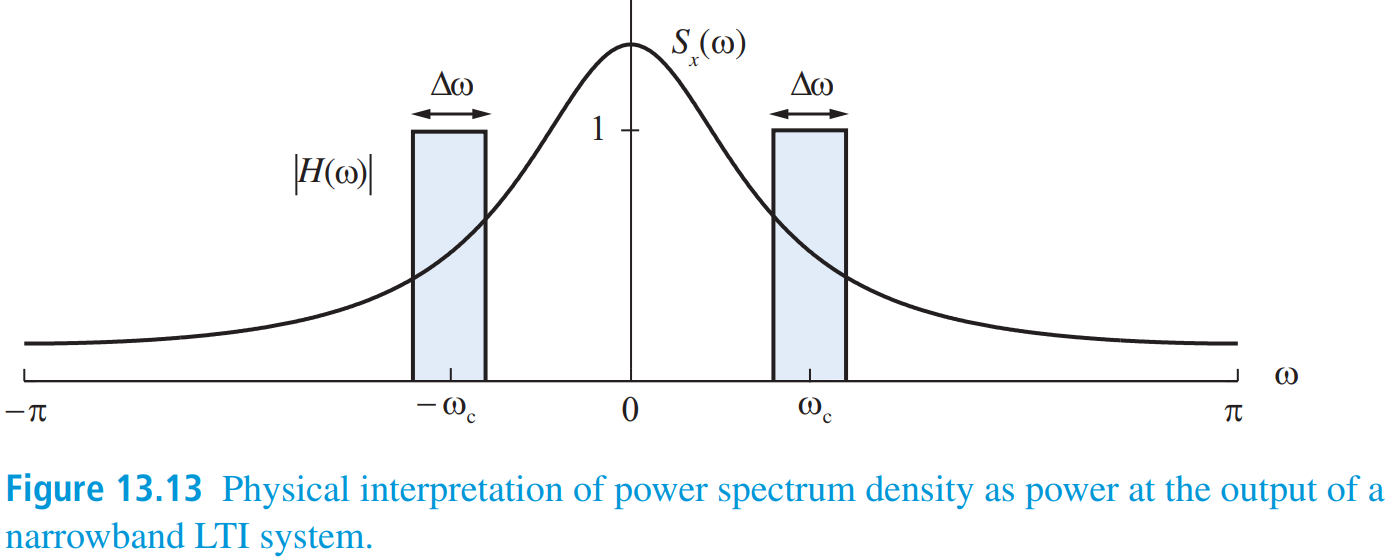

Now, the question is how to do we compute the power spectrum of our ideal narrow bandpass filter when the signal is random?

The answer is to compute the the average output of the filter.

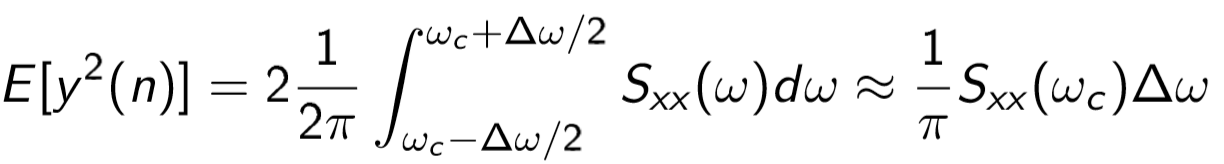

Since the spectrum is symmetic around zero, we get power contribution from both sides of zero. This is called a double-sided spectrum. Therefore, we have $2\frac{1}{2\pi }$ in the equation above.

### PSD Estimation

Since we cannot have a mathematical model of random signals instead we use a statistical model. The Power Spectrum Density describes the variance (or power) of a random signal as a function of frequency. PSD can tell us where the energy is distributed. 

Typically, we can estimate the power spectrum given a set of data. There is two main categories for spectrum estimation.

a) Non-parametric Methods: do not assume that a particular model generated the data. In this case, we just use the FFT

b) Parameteric Methods: assume that the data is generated in a certain way. The general approach is:

- Measure and get some data $x\left(n\right)$

- Use the data to estimate the model parameters e.g. ARMA coefficients

- Express the estimated PSD $\hat{S_{\mathrm{xx}} } \left(\omega \right)$ as a function pof the model parameters. 

#### Parametric Model: ARMA(p, q)

For example, we might assume that the data is the output of the LTI system with frequency response $H\left(e^{j\omega } \right)$ given white noise signal as input:

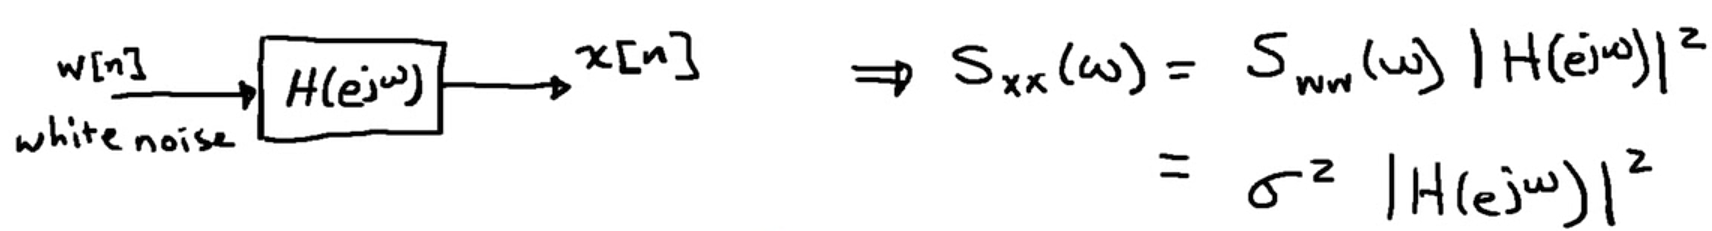

There are several different models that can be used to estimate the PSD.

- AR(q) model, autoregressive model, all-pole model, only poles in its frequency response.

- MA(p) model, moving average, only zeros in its frequency response.

- ARMA(q, p) model

Whether a model has poles, zeros or pole-zeros results in different characteristic of the PSD estimate.

#### Parametric Model: Sinusoids with Additive Noise

Another example of a parametric method is Sinusoid in Noise model. Here, the model assumes that the data that we have measured $x\left\lbrack n\right\rbrack$ consists of combination of multiple sinusoids with additive noise $w\left(n\right)$. With this model, the PSD is:

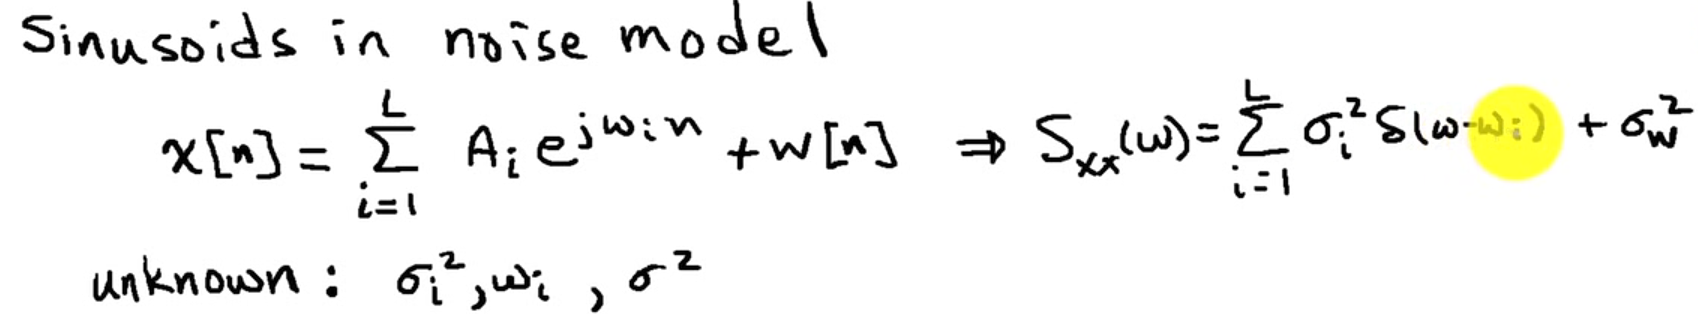

If we know the parameters $\sigma_i^2$, $\omega_i$ and $\sigma_w^2$ then we our PSD.

#### Non-parametric Methods vs Parameteric Methods

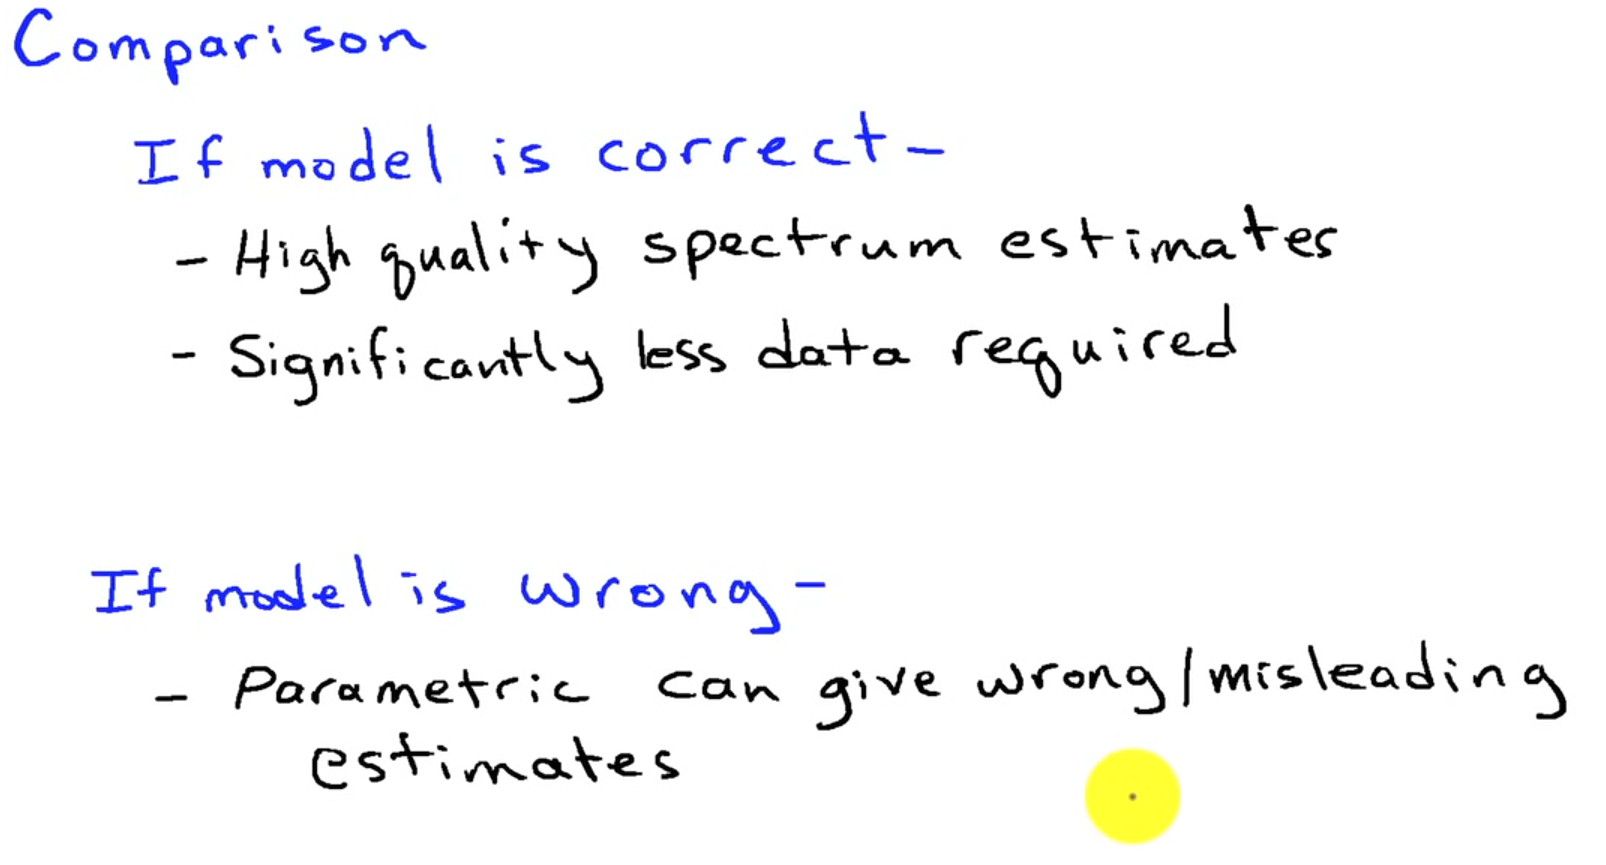

### Computing PSD of Example Signals

#### White Noise

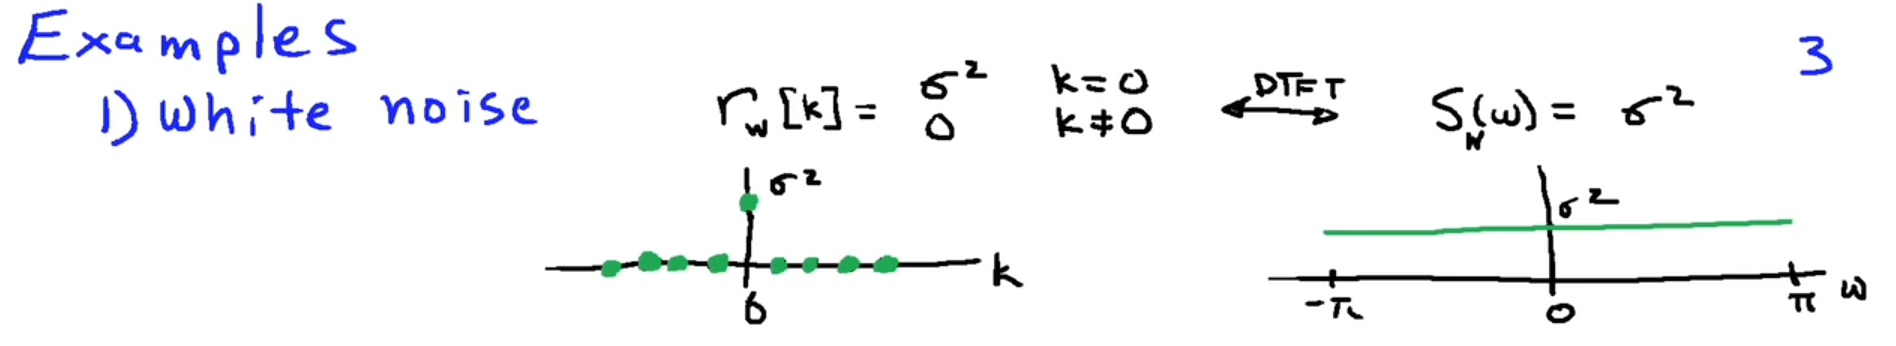

The power spectral density of white noise is constant which means that we have the same power across all frequencies. This signal is called white noise because the power is equally distributed across the entire spectrum.

#### Random Sinusoid

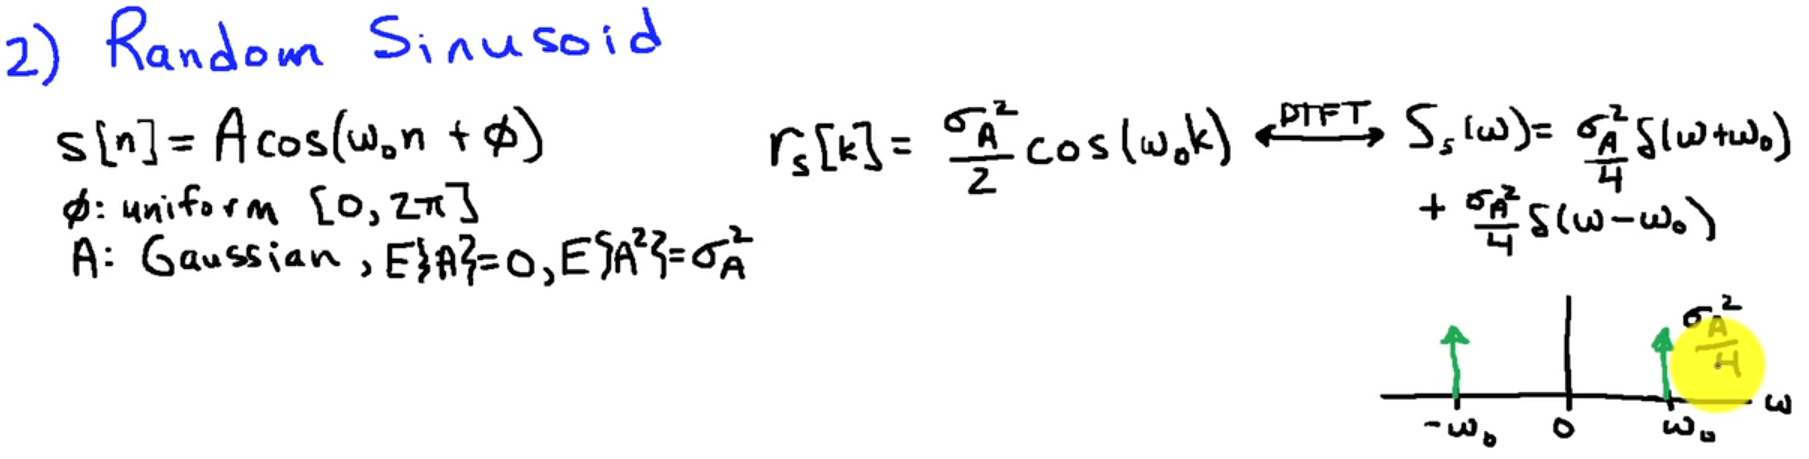

The power spectral density shows that the power is concentrated at $\pm \omega_0$. The area under these concentrations is $\frac{1}{4}\sigma A^2$.

#### Coloured Noise

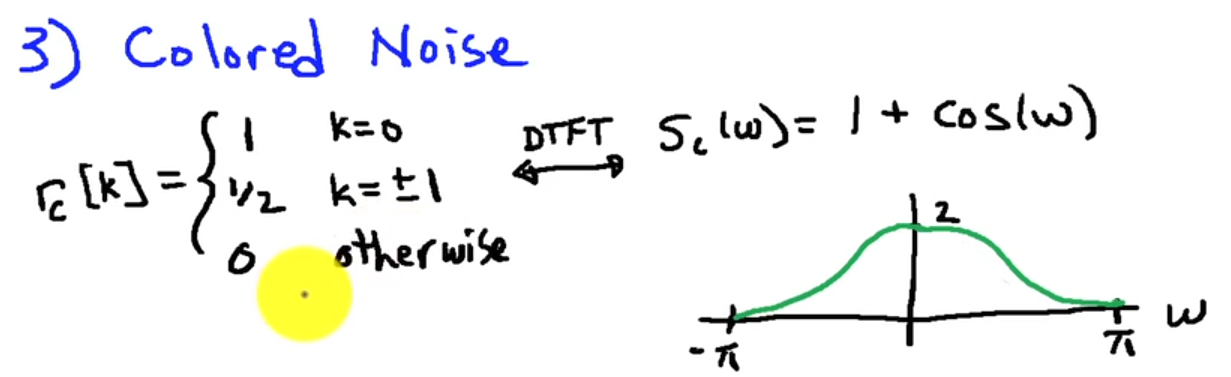

## Coherence Function

### Cross Power Spectrum Density

Cross power spectrum density $S_{\mathrm{yx}} \left(\omega \right)$ is the Fourier Transform of the cross-correlation:

        
$$S_{\textrm{yx}} \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } r_{\mathrm{yx}} \left(\ell \right)e^{-j\omega \;\ell }$$


The cross power spectrum compares two signals and computes how much the **two signals oscillate in phase**. If we get a large value at a given frequency $\omega_0$, then this means the two signals are oscilliting together at $\omega_0$. If $S_{\textrm{yx}} \left(\omega_0 \right)$ is small then the two signal are not in phase at $\omega_0$. 

`Why do we care?` The cross power spectrum density allows us to define a coherence function.

### Definition of the Coherence Function

The (magnitude squared) coherence function allows us to determine in an elegant way when a system is linear.

Formally, the (magnitude squared) coherence function is defined:

        
$${\left|\gamma_{\mathrm{yx}} \left(\omega \right)\right|}^2 =\frac{{\left|S_{\mathrm{yx}} \left(\omega \right)\right|}^2 }{S_{\mathrm{yy}} \left(\omega \right)S_{\mathrm{xx}} \left(\omega \right)}$$


where $0\le {\left|\gamma_{\mathrm{yx}} \left(\omega \right)\right|}^2 \le 1$i.e., the function yields a number between zero and one.

For a linear system, the coherence function should be 1 or very close to it:

        
$${\left|\gamma_{\mathrm{yx}} \left(\omega \right)\right|}^2 =1$$


**The coherence function of a perfect linear system is equal to 1.**

However, in the real-world we don't always get a coherence of 1. Suppose we want to determine whether a system or a filter is linear:

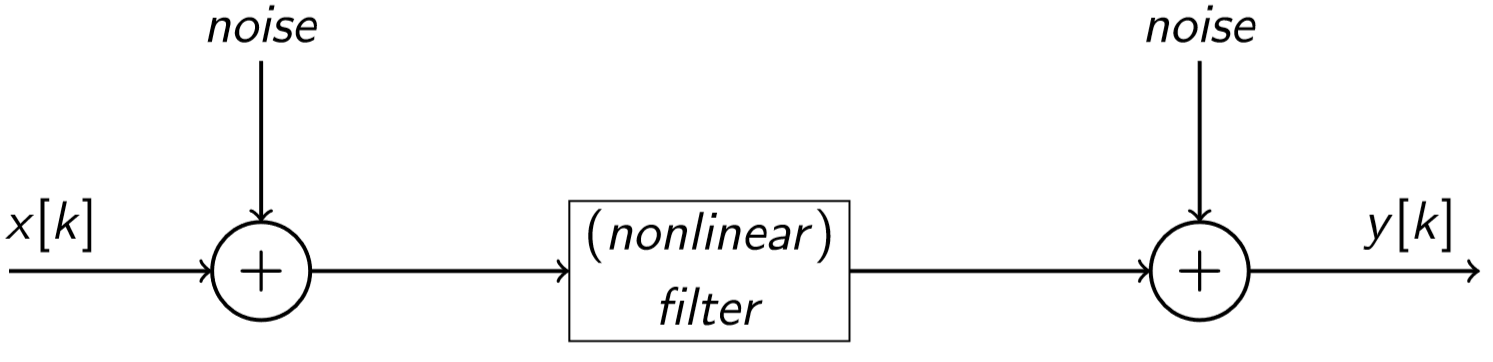

There are three primal factors that causes the coherence function to fall below 1.

- Factor 1: After we measure $x\left(n\right)$, some unaccounted noise creeps into the signal before going into the system. 

- Factor 2: Some unaccounted noise creeps into the output signal before we measure it.

- Factor 3: The filter contains some nonlinear components.

***Important lesson:*** The coherence function is a tool that we can use to measure whether any given system is actually linear. Since the coherence function measures how close a system is linear, we don't know whether a low coherence is due to noise or a non-linear filter. 

### Coherence Estimates in MATLAB

clear variables;

#### High-Pass IIR filter

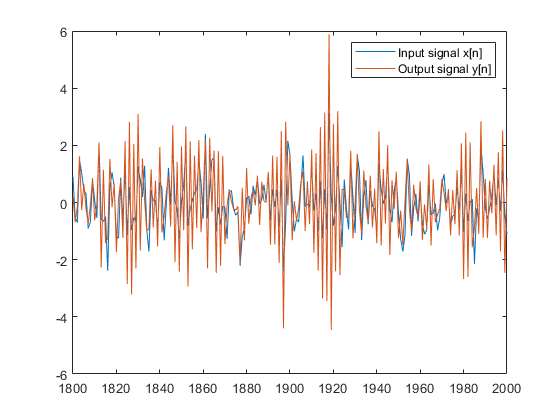

N = 2000;
n = 1800:N;

% Create an input signal of random numbers
x = randn(N, 1);

% Define a high pass IIR filter that attenuates low
% frequencies and amplifies high frequencies
b = 1;
a = [1, 0.8];

y = filter(b, a, x);
plot(n, x(n), n, y(n));
legend('Input signal x[n]', 'Output signal y[n]')

We can plot the magnitude response to see which frequencies the filter is attenuating and which frequency components it is amplifying:

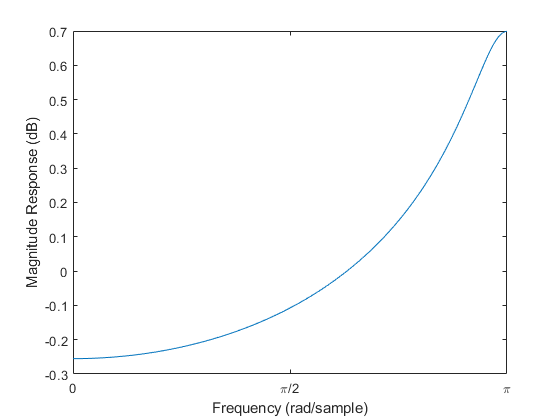

[H, w] = freqz(b, a, 'whole');
plot(w, log10(abs(H)));
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude Response (dB)')
xlim([0, pi]);

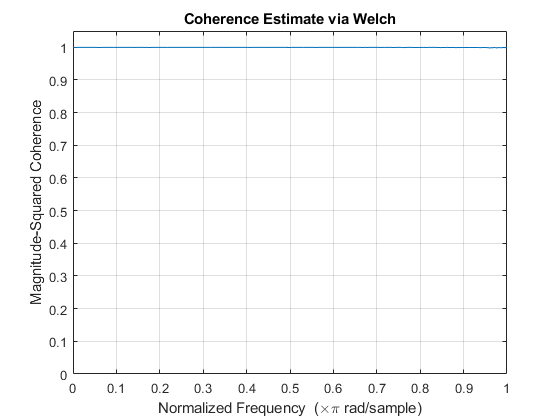

% Compute and plot the coherence estimate
mscohere(y, x);
ylim([0, 1.05]);

Notice that the estimate coherence function is 1. This is not a surprise because we are sending the input signal through a LTI system.

#### High-pass filter with noise at the output

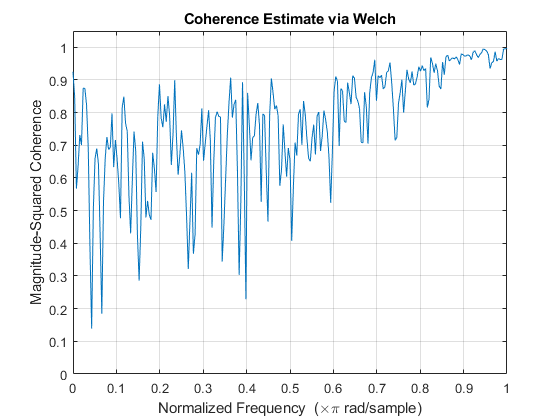

% Define a high pass IIR filter that attenuates low
% frequencies and amplifies high frequencies
noise = 0.5;
y = filter(b, a, x);
y = y + noise*randn(N, 1);

% Compute and plot the coherence estimate
mscohere(y, x);
ylim([0, 1.05]);

We observe that the coherence falls below 1 although we have a LTI filter because we have added a lot of noise to the output signal. Notice that there are low coherence at the low frequencies and high coherence at the high frequencies. This is because the high-pass filter attenuates low frequencies, and amplifies high frequencies.

If the noise is reduced, we get close to 1:

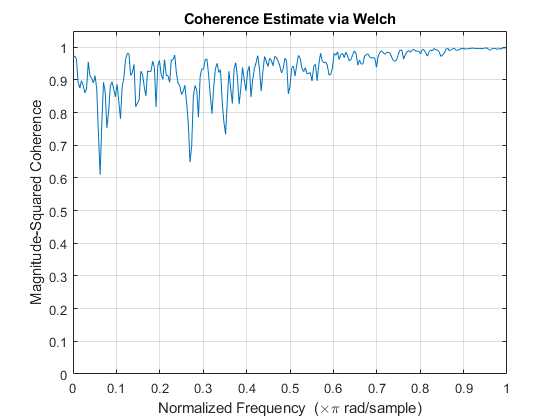

noise = 0.2;
y = filter(b, a, x);
y = y + noise*randn(N, 1);

% Compute and plot the coherence estimate
mscohere(y, x);
ylim([0, 1.05]);

#### High-pass filter with noise at the input

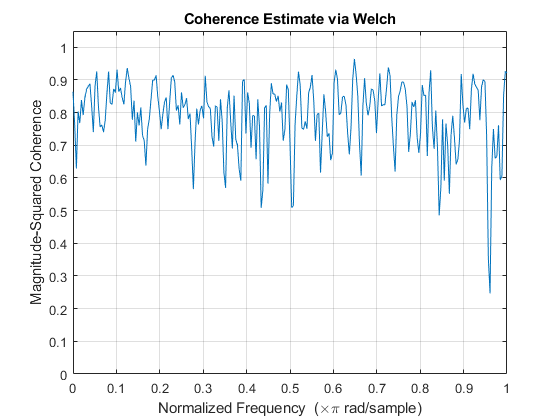

noise = 0.5;
y = filter(b, a, x + noise*randn(N, 1));
mscohere(y, x);
ylim([0, 1.05]);

The additional noise is also being filtered so we have equal amount.

#### Nonlinear filter

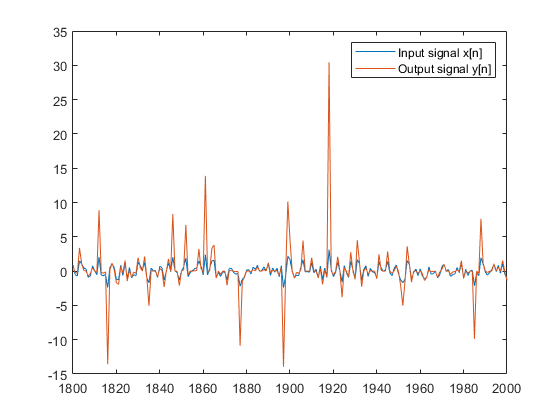

% Take each sample and cube it
y = x.^3; 
plot(n, x(n), n, y(n));
legend('Input signal x[n]', 'Output signal y[n]')

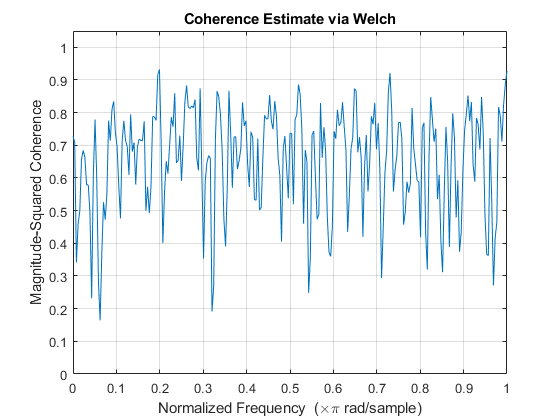

mscohere(y, x);
ylim([0, 1.05]);

The coherence is all over the place. 

***Lesson:*** Since the coherence function measures how close a system is linear, we don't know whether a low coherence is due to noise or a non-linear filter.

In practice, the coherence function is close to 1. The difference $1-\mathrm{mscohere}\left(y,x\right)$ tells us how well we can remove noise.

#### Nonlinear filter via clipping

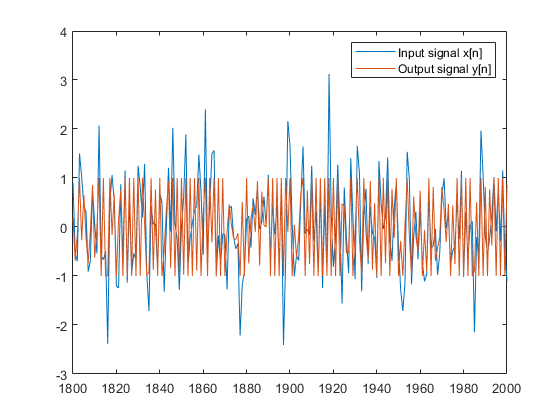

% Non-linear filter via clipping
y = filter(b, a, x);
for k=1:N
    if y(k)>1
        y(k)=1;
    end
    if y(k)<-1
        y(k)=-1;
    end
end
plot(n, x(n), n, y(n));
legend('Input signal x[n]', 'Output signal y[n]')

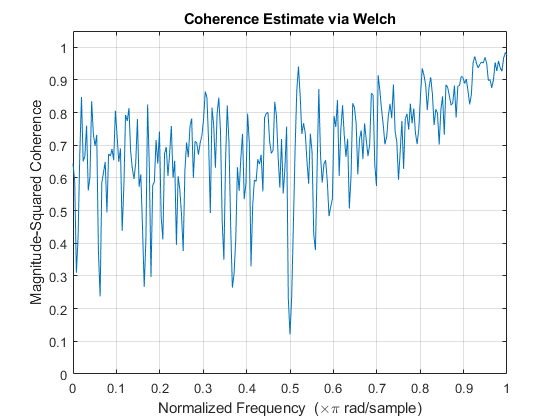

mscohere(y, x);
ylim([0, 1.05]);

We see more coherence in the high frequencies than the low frequencies. Research why? 

#### Comb Filter

Let us defined a comb filter which has the difference equation:


$$y\left\lbrack n\right\rbrack =b_0 x\left\lbrack n\right\rbrack +b_M x\left\lbrack n-M\right\rbrack$$


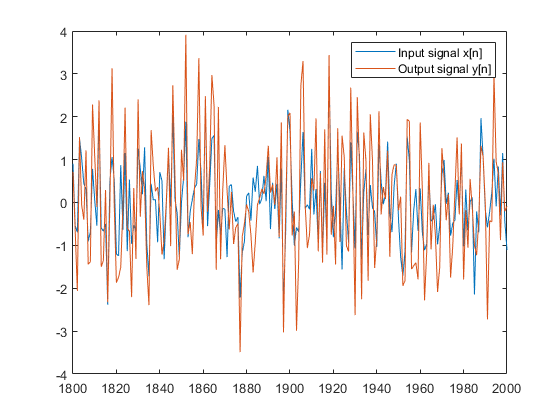

% Define a comb filter
b = [1 0 0 0 0 0 1];
a = 1;
y = filter(b, a, x);
plot(n, x(n), n, y(n));
legend('Input signal x[n]', 'Output signal y[n]')

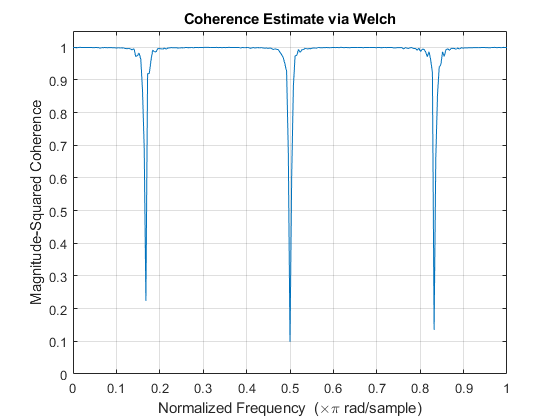

% Compute and plot the coherence estimate
mscohere(y, x);
ylim([0, 1.05]);

Notice that the coherence function dips at certain frequencies. This is because the comb filter removes certain frequency components of the input signal. Thefore, there is no coherence between the input signal and the output signal at those specific frequencies since the output signal does not contain these filtered frequencies.

The filter has 6 zeros on the unit circle, which means that it is removing 6/2=3 frequency components:

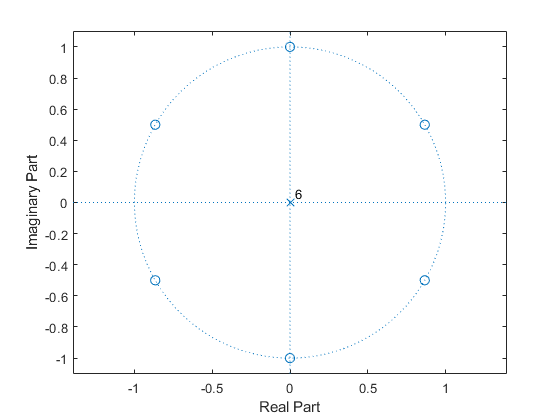

zplane(b, a)

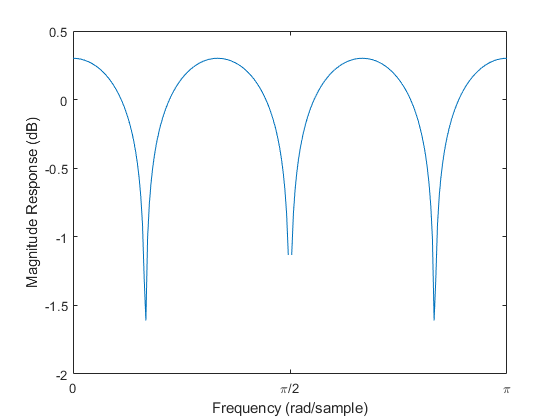

% Plot the magnitude response to see which frequency
% components are being attenuated
[H, w] = freqz(b, a, 'whole');
plot(w, log10(abs(H)));
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude Response (dB)')
xlim([0, pi]);

## Problems

### Compute PSD from an ACRS

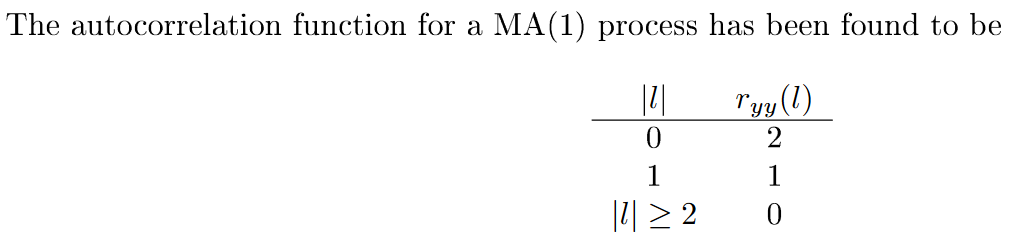

Whenever we need to compute the PSD based on an autocorrelation sequence, we use Eq. (13.119):

        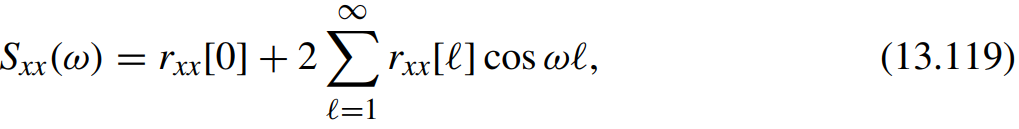

Plugging in our values, we get:

        
$$S_{\textrm{yy}} \left(\omega \right)=2+2\left(1\mathrm{cos}\left(1\omega \right)\right)=2+2\mathrm{cos}\left(\omega \right)$$


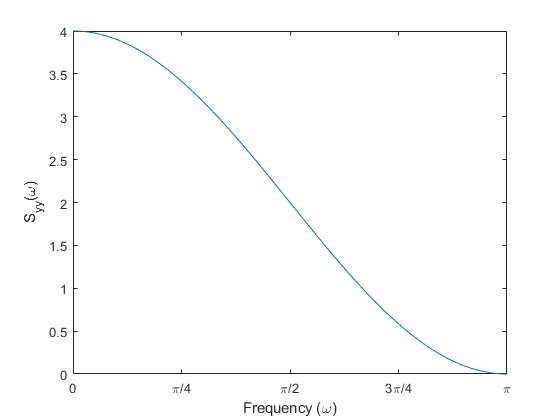

w=0:0.001:2*pi;
S_yy = 2 + 2*cos(w);
plot(w, S_yy);
xlabel('Frequency (\omega)');
ylabel('S_{yy}(\omega)');
set(gca,'XTick',0:pi/4:pi) 
set(gca,'XTickLabel',{'0', '\pi/4', '\pi/2', '3\pi/4', '\pi'})
xlim([0, pi])

### Quiz: Determine if two sinusoids have the same PSD?

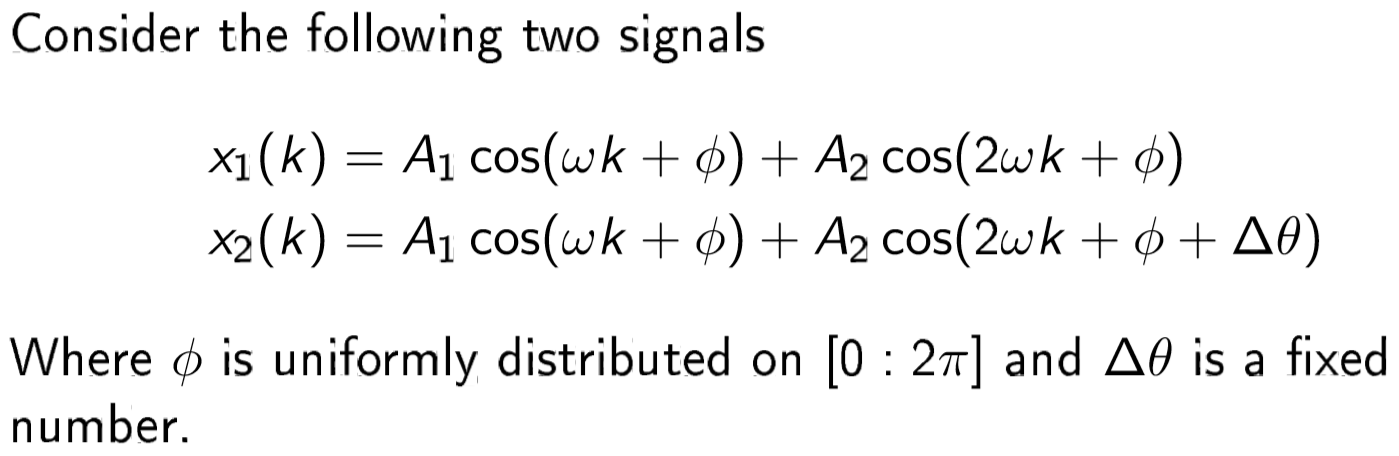

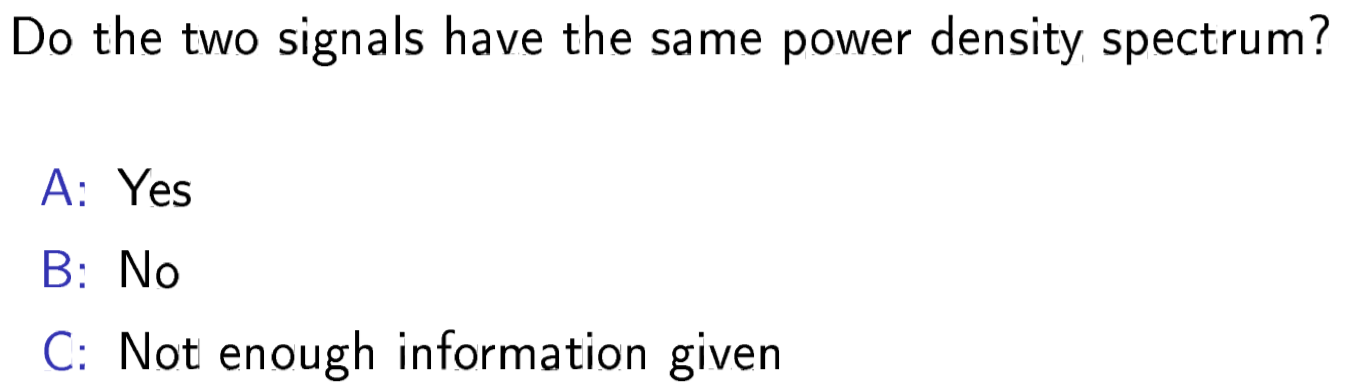

The answer is A; the two signals have the power density spectrum.

In this quiz, we need to compare the PSD of the two signals; $x_1 \left(k\right)$ and $x_2 \left(k\right)$ 

The only difference between the two signals is that $x_2 \left(k\right)$ is a fixed phase shift of $\Delta \theta$

In order to compare compute the PSD, we need to compute the autocorrelation of the signal.

Last week (see problem ADSI Problem 4.4.3) we computed the autocorrelation of a generic real sinusoid $x\left(n\right)=\mathrm{Acos}\left(\omega n+\phi \right)$, which was:

        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\cos \left(\omega \ell \right)$$


From this result, we see that the phase does not matter. Therefore, the autocorrelation of $x_1 \left(k\right)$ and $x_2 \left(k\right)$ are the same.

This means that the corresponding PSDs are also the same.

**Lesson: when you compute the PSD, we only know the amount of energy at each given frequency. But we have no clue about the phase, which is essentially lost.**

### Quiz: How do we measure if a system is LTI? 

In this class, we always make the assumptions that our systems are LTI system, but how do we actually know if a real-world system is LTI.

How do we measure if a system is linear and time-invariant?

We can measure if a system is linear by checking the two linearity properties:

    1) $T\left(u+v\right)=T\left(u\right)+T\left(v\right)$

- Feed the system with the sum of two signals $x_1 \left(n\right)+x_2 \left(n\right)$ and observe the output $y\left(n\right)$. 

- Feed the system with $x_1 \left(n\right)$ to record the output $y_1 \left(n\right)$.

- Feed the system with $x_2 \left(n\right)$ to record the output $y_2 \left(n\right)$.

- Now, the output $y\left(n\right)$ should be the same as $y_1 \left(n\right)+y_2 \left(n\right)$

    2) $T\left(A\;v\right)=A\;T\left(v\right)$

- Feed the system with a signal with certain amplitude $A$ e.g. $A=42$. Record the output $y\left(n\right)$

- Feed the system with the same signal but where the amplitude is 1. Record the output $z\left(n\right)$

- The two outputs should have following relations: $y\left(n\right)=42\cdot z\left(n\right)$

We can measure if a system is time-invariant as follows:

- Feed the system with a known signal $x\left(n\right)$ and measure the output $y\left(n\right)$

- Feed the system with the same signal but shifted $x\left(n-k\right)$ the output should also be shifted $y\left(n-k\right)$

A more elegant approach is to compute the coherence function:

        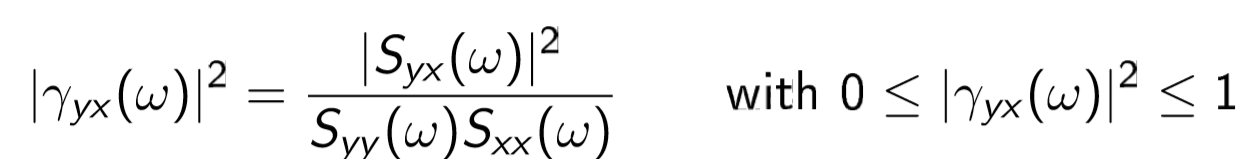

For a linear system, the coherence function should be 1 or very close to it:

        
$${\left|\gamma_{\mathrm{yx}} \left(\omega \right)\right|}^2 =1$$


## ADSI Problem 4.7: Coherence function

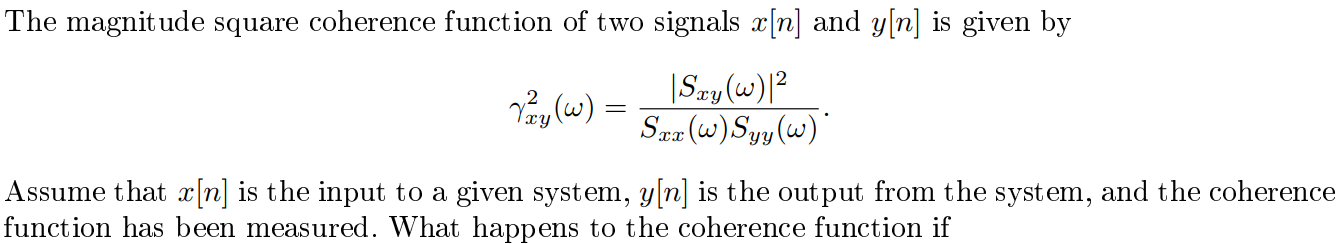

### 1) What happens to the coherence function if gain is increased from 1 to 2:

To answer this question, we need to compute the new coherence function. Power Spectral Density $S_x \left(\omega \right)$ and Cross-Power Spectral Density $S_{\mathrm{yx}} \left(\omega \right)$ are essentially the discrete-time Fourier Transform of the corresponding auto-correlation and cross-correlation.

So we need to compute those first. The autocorrelation for the input signal is the same because the input signal has not changed. We need to compute the autocorrelation for the new output signal.

Let $z\left(n\right)=2y\left(n\right)$ denote the new output signal.

The autocorrelation for the new output signal $r_z \left(\ell \right)$ can be computed as follows:

        
$$r_z \left(\ell \right)=E\left\lbrack z\left(n\right)z\left(n-\ell \right)\right\rbrack$$


        
$$r_z \left(\ell \right)=E\left\lbrack 2y\left(n\right)2y\left(n-\ell \right)\right\rbrack$$


        
$$r_z \left(\ell \right)=4E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


        
$$r_z \left(\ell \right)=4r_y \left(\ell \right)$$


To find the PSD, we take the Fourier Transform:

        
$$S_z \left(\omega \right)=R_z \left(e^{j\omega } \right)=4R_y \left(e^{j\omega } \right)=4S_y \left(\omega \right)$$


This means that if the output gain is increased by 2, the PSD increases by a factor of 4.

Next, we need compute the cross-correlation $r_{\mathrm{zx}} \left(\ell \right)$:

        
$$r_{\mathrm{zx}} \left(\ell \right)=E\left\lbrack z\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=E\left\lbrack 2y\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=2E\left\lbrack y\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=2r_{\mathrm{yx}} \left(\ell \right)$$


To find the PSD, we take the Fourier Transform:

        
$$S_{\mathrm{zx}} \left(\omega \right)=R_{\mathrm{zx}} \left(e^{j\omega } \right)=2R_{\mathrm{yx}} \left(e^{j\omega } \right)=2S_{\mathrm{yx}} \left(\omega \right)$$


Finally, we can compute the coherence function:

        
$${\left|\gamma_{\textrm{zx}} \left(\omega \right)\right|}^2 =\frac{{\left|S_{\textrm{zx}} \left(\omega \right)\right|}^2 }{S_z \left(\omega \right)S_{\textrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|2S_{\textrm{yx}} \left(\omega \right)\right|}^2 }{4S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|2\right|}^2 {\left|S_{\textrm{yx}} \left(\omega \right)\right|}^2 }{4S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|S_{\textrm{yx}} \left(\omega \right)\right|}^2 }{S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$


The coherence function with the new output signal is the same the original coherence function.

This means that increasing the output gain by 2, nothing happens to the coherence function.

### 2) What happens to the coherence function if a delay happens in the measurement?

Let $z\left(n\right)=y\left(n-D\right)$

First, compute the autocorrelation for the new output signal $r_z \left(\ell \right)$:

        
$$r_z \left(\ell \right)=E\left\lbrack y\left(n-D\right)y\left(n-D-\ell \right)\right\rbrack$$


Let $m=n-D$ then we can write the above equation as:

        
$$r_z \left(\ell \right)=E\left\lbrack y\left(m\right)y\left(m-\ell \right)\right\rbrack$$
  

This expression is the same as $r_y \left(\ell \right)$ so the delayed output signal does not change the autocorrelation:

        
$$r_z \left(\ell \right)=r_y \left(\ell \right)$$


Next, we compute the cross-correlation:

        
$$r_{\mathrm{zx}} \left(\ell \right)=E\left\lbrack z\left(n\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=E\left\lbrack y\left(n-D\right)x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=E\left\lbrack y\left(n\right)x\left(n-\ell +D\right)\right\rbrack$$


        
$$r_{\textrm{zx}} \left(\ell \right)=r_{\mathrm{yx}} \left(\ell +D\right)$$


To find the Fourier Transform, we can use the Fourier pair: $f\left(t-t_0 \right)\leftrightarrow F\left(e^{j\omega \;} \right)e^{-j\omega t_0 }$

        
$$R_{\mathrm{zx}} \left(e^{j\omega } \right)=R_{\mathrm{yx}} \left(e^{j\omega } \right)e^{j\omega D} =S_{\mathrm{yx}} \left(\omega \right)e^{j\omega D}$$


Finally, we can compute the coherence function:

        
$${\left|\gamma_{\textrm{zx}} \left(\omega \right)\right|}^2 =\frac{{\left|S_{\textrm{zx}} \left(\omega \right)\right|}^2 }{S_z \left(\omega \right)S_{\textrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|e^{j\omega D} S_{\textrm{yx}} \left(\omega \right)\right|}^2 }{S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$

$$=\frac{{\left|e^{j\omega D} \right|}^2 \;{\left|S_{\textrm{yx}} \left(\omega \right)\right|}^2 \;}{S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$


The norm of the $e^{j\omega D}$ is 1 because this quantity describes a point on the unit circle:

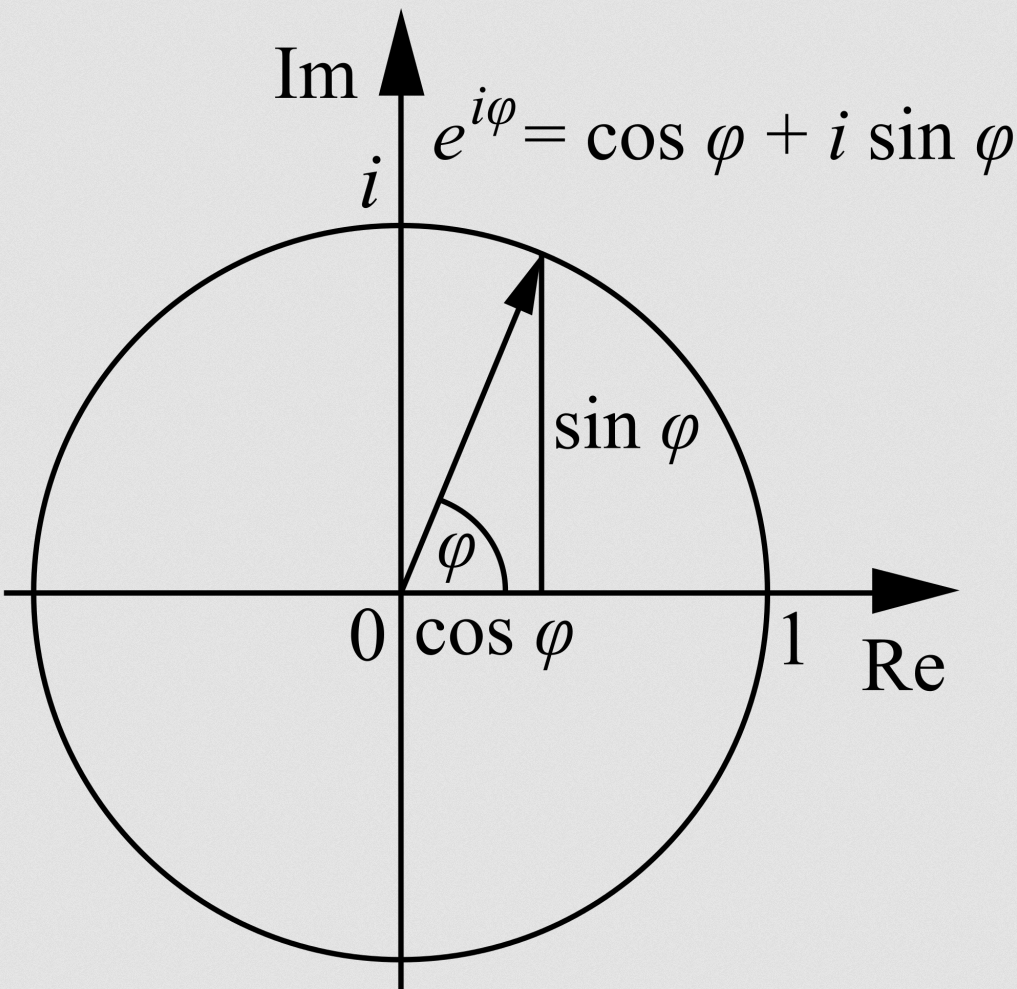

Since the square of 1 is 1, the coherence function is the same:

        
$${\left|\gamma_{\textrm{zx}} \left(\omega \right)\right|}^2 =\frac{{\left|S_{\textrm{yx}} \left(\omega \right)\right|}^2 \;}{S_y \left(\omega \right)S_{\mathrm{x}} \left(\omega \right)}$$


This means that a delay in the measurement does not effect the coherence function!

# Functions